Get videos into matrix form.

name_A = "s2.mp4";
name_B = "n2.mp4";
pixScale_A = .00127; %m/px
pixScale_B = .00113; %m/px
fps_A = 60;
fps_B = 60;
theta = 90; %angle between the axes of the cameras
A = ReadFrames(name_A,720,1280);

    "Making Video Reader for "    "s2.mp4"

Reading in frames:
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



B = ReadFrames(name_B,720,1280);

    "Making Video Reader for "    "n2.mp4"

Reading in frames:
    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200

   210

   220

   230

   240

   250

   260

   270

   280



Next, determine the synchronization time by using implay and assign the sync times to sync frames variables.

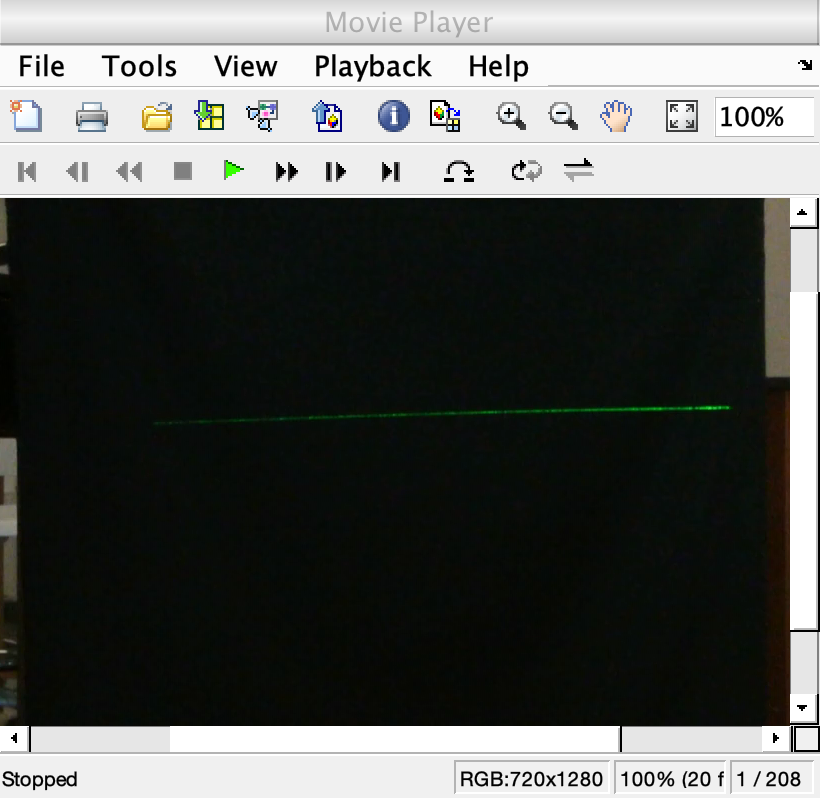

implay(uint8(A));

syncFrame_A = 109;

Same with B.

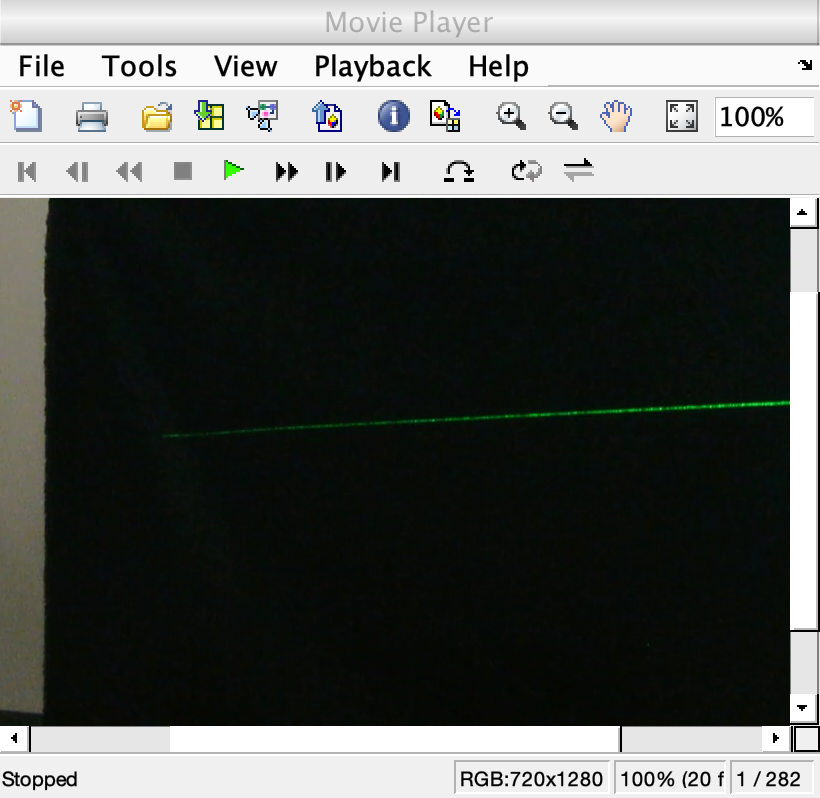

implay(uint8(B));

syncFrame_B = 183;

Turn the A video into tracks.

Particlexyt_A = FindParticles(10,300, A);

Tracking Movement
Highlighting Particles
Finding Particle Locations



param.good=10;
param.mem=2;
param.quiet=0;
param.dim=2;

Tracks_A = track(Particlexyt_A, 50,param);

49 of49 done.  Tracking1 particles1 tracks total


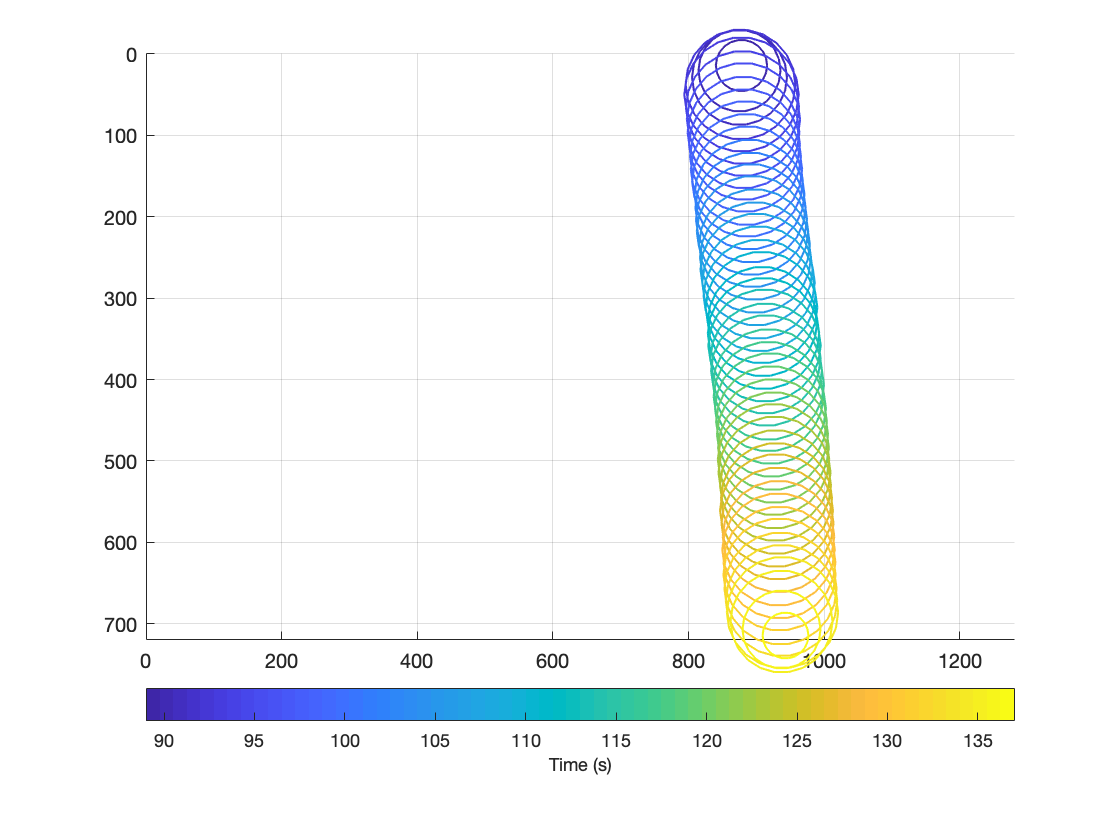


scatter3(Tracks_A(:,1), Tracks_A(:,2), Tracks_A(:, 7), Tracks_A(:,3), Tracks_A(:,6));
video_dim = size(A);
axis([0 video_dim(2) 0 video_dim(1)])
axis ij
c = colorbar('southoutside');
c.Label.String = 'Time (s)';

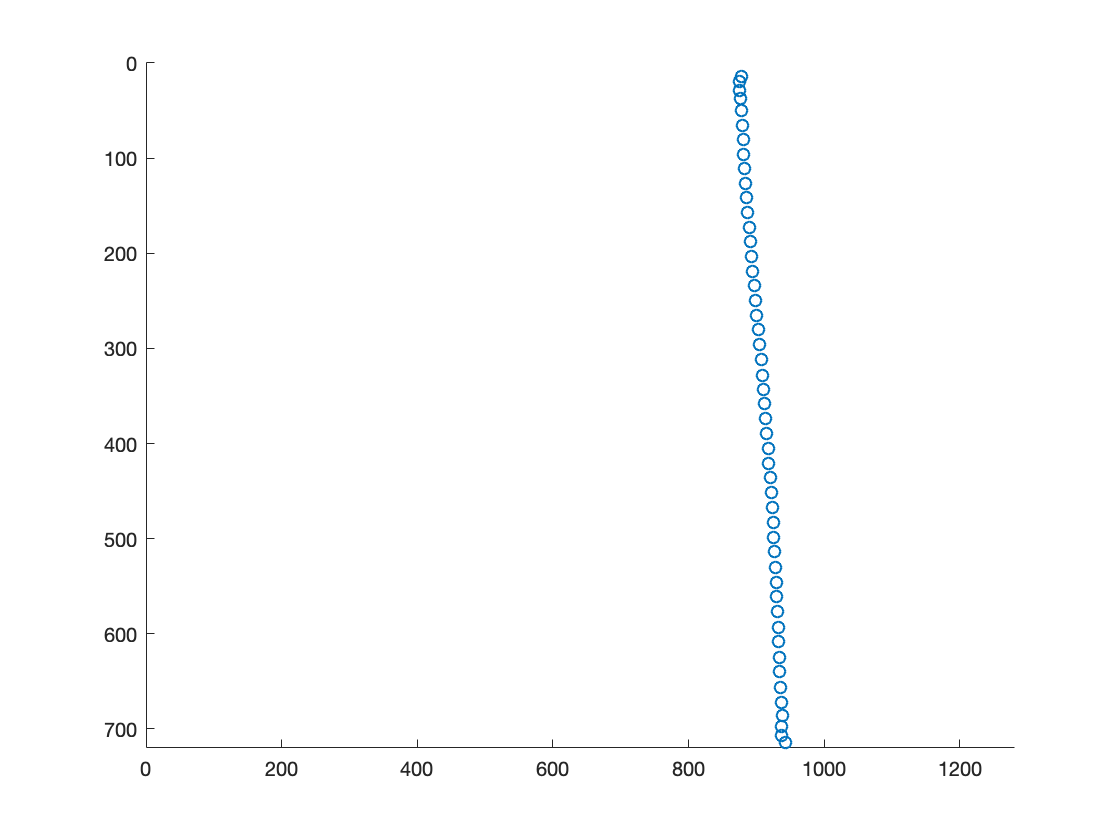

num_track_A = 1;
loc_A = Tracks_A(:,7)==num_track_A;
frame_num_A = Tracks_A(loc_A,6);
y_A = Tracks_A(loc_A,1);
y_A_zero = Tracks_A(Tracks_A(:,6)==syncFrame_A,1);
z_A = Tracks_A(loc_A,2);
z_A_zero = Tracks_A(Tracks_A(:,6)==syncFrame_A,2);
scatter(y_A,z_A)
axis([0 video_dim(2) 0 video_dim(1)])
axis ij

Determine whether there should be any frames cut out, either on the front or backend.

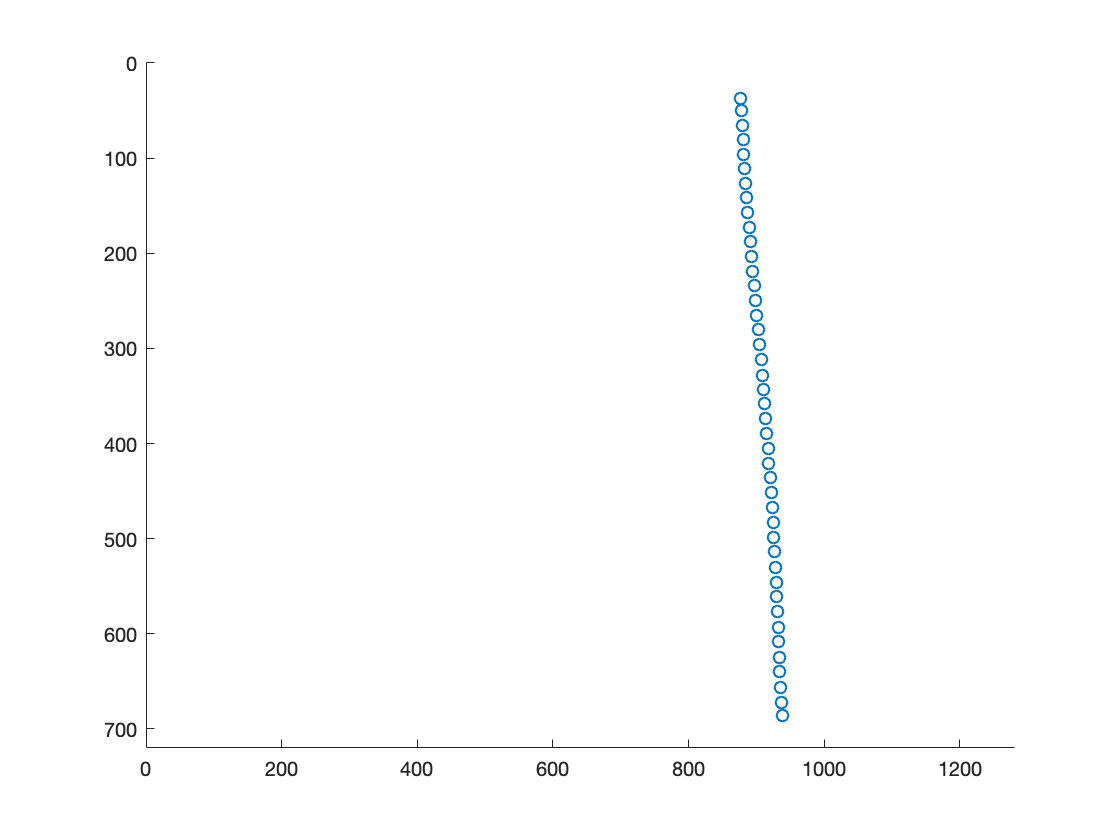

cutoff_A_front = 4;
cutoff_A_back = 3;
y_A = y_A(cutoff_A_front:end);
z_A = z_A(cutoff_A_front:end);
frame_num_A = frame_num_A(cutoff_A_front:end);

y_A = y_A(1:end-cutoff_A_back);
z_A = z_A(1:end-cutoff_A_back);
frame_num_A = frame_num_A(1:end-cutoff_A_back);
scatter(y_A,z_A)
axis([0 video_dim(2) 0 video_dim(1)])
axis ij

Particlexyt_B = FindParticles(10,300, B);

Tracking Movement
Highlighting Particles
Finding Particle Locations



param.good=10;
param.mem=2;
param.quiet=0;
param.dim=2;

Tracks_B = track(Particlexyt_B, 50,param);

47 of47 done.  Tracking1 particles1 tracks total


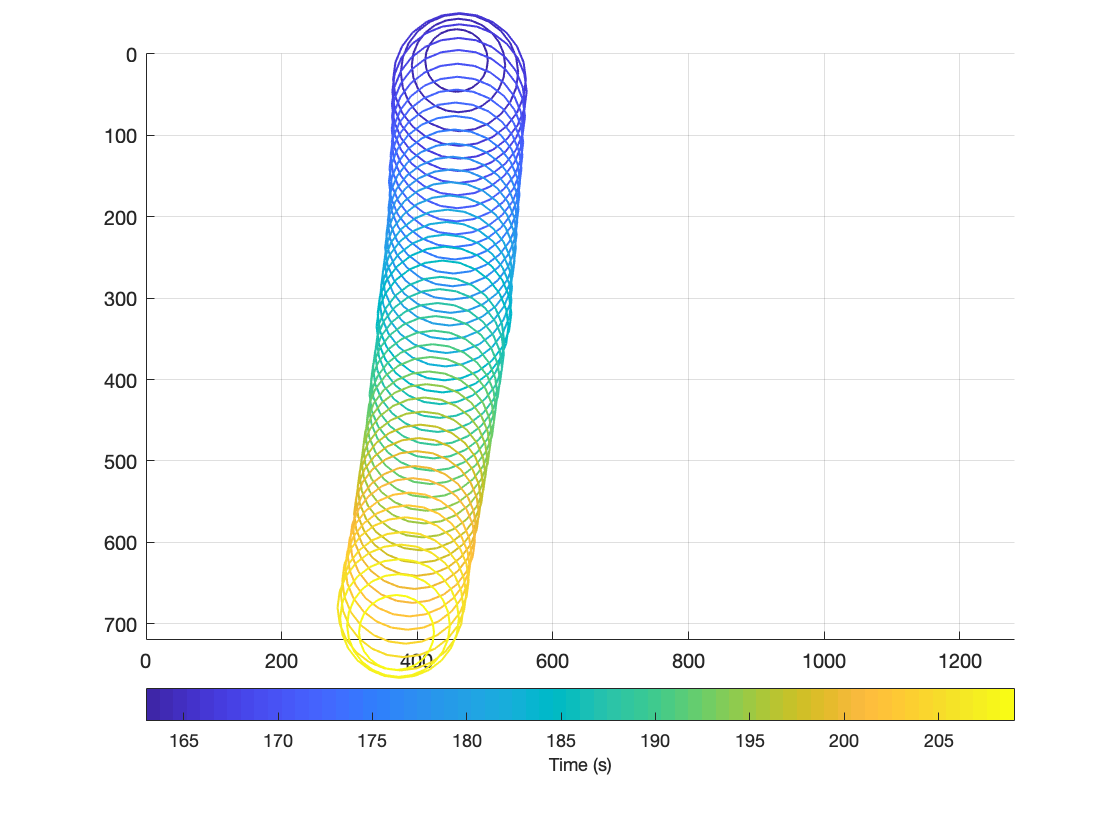

scatter3(Tracks_B(:,1), Tracks_B(:,2), Tracks_B(:, 7), Tracks_B(:,3), Tracks_B(:,6));
video_dim = size(B);
axis([0 video_dim(2) 0 video_dim(1)])
axis ij
c = colorbar('southoutside');
c.Label.String = 'Time (s)';

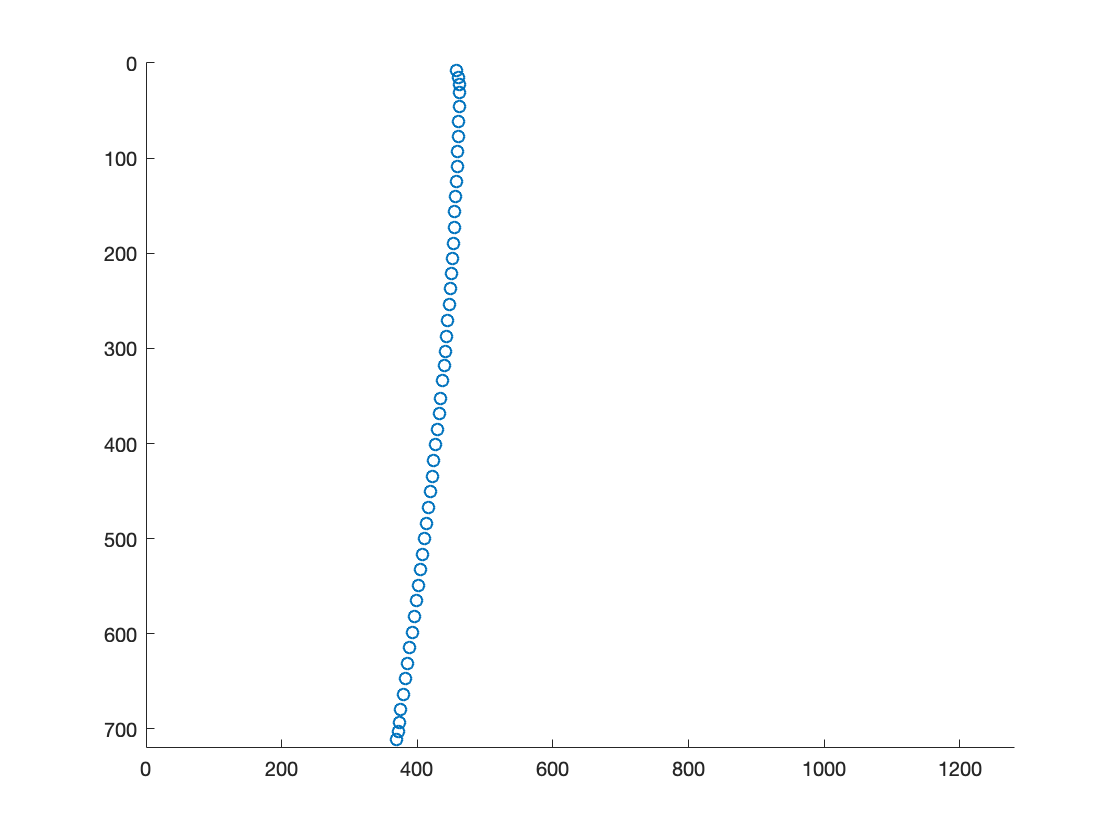

num_track_B = 1;
loc_B = Tracks_B(:,7)==num_track_B;
frame_num_B = Tracks_B(loc_B,6);
x_B = Tracks_B(loc_B,1);
x_B_zero = Tracks_B(Tracks_B(:,6)==syncFrame_B,1);
z_B = Tracks_B(loc_B,2);
z_B_zero = Tracks_B(Tracks_B(:,6)==syncFrame_B,2);
scatter(x_B,z_B)
axis([0 video_dim(2) 0 video_dim(1)])
axis ij

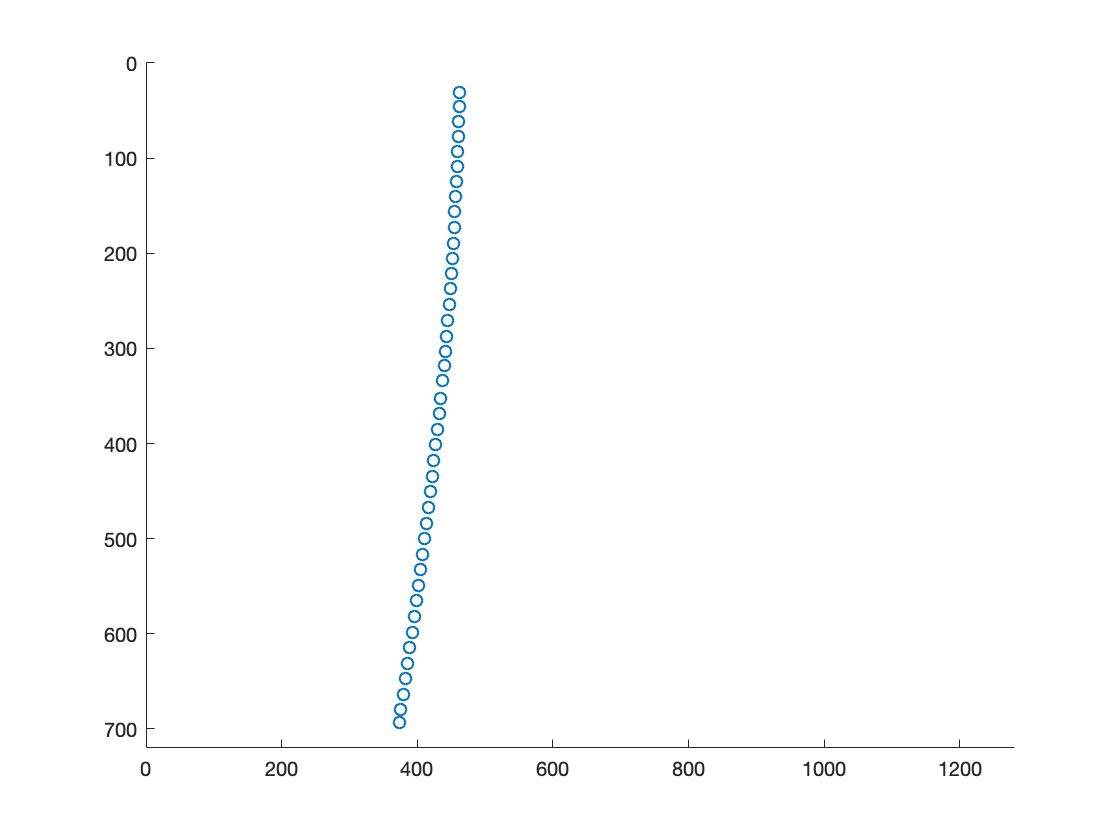

cutoff_B_front = 4;
cutoff_B_back = 2;
x_B = x_B(cutoff_B_front:end);
z_B = z_B(cutoff_B_front:end);
frame_num_B = frame_num_B(cutoff_B_front:end);

x_B = x_B(1:end-cutoff_B_back);
z_B = z_B(1:end-cutoff_B_back);
frame_num_B = frame_num_B(1:end-cutoff_B_back);
scatter(x_B,z_B)
axis([0 video_dim(2) 0 video_dim(1)])
axis ij

Translate the positions into real coordinates by placing the calibration point as the origin and converting from pixels to actual distances.

t_A = (frame_num_A-syncFrame_A)/fps_A;
t_B = (frame_num_B-syncFrame_B)/fps_B;
x_B = (x_B-x_B_zero)*pixScale_B;
z_B = (z_B-z_B_zero)*pixScale_B;
y_A = (y_A-y_A_zero)*pixScale_A;
z_A = (z_A-z_A_zero)*pixScale_A;

The vectors will be of different lengths (i.e., one camera might be tracking the diaspore for longer than the other camera), so potentially need to cut off entries from either vector.

t_min = max(t_A(1),t_B(1)); %max because both t_A and t_B are negative
y_A = y_A(t_A>=t_min);
z_A = z_A(t_A>=t_min);
t_A = t_A(t_A>=t_min);

x_B = x_B(t_B>=t_min);
z_B = z_B(t_B>=t_min);
t_B = t_B(t_B>=t_min);

t_max = min(t_A(end),t_B(end));
y_A = y_A(t_A<=t_max);
z_A = z_A(t_A<=t_max);
t_A = t_A(t_A<=t_max);

x_B = x_B(t_B<=t_max);
z_B = z_B(t_B<=t_max);
t_B = t_B(t_B<=t_max);

Plot the two z values against each other to see how well they match up. Note that MATLAB measures positive z as downward.

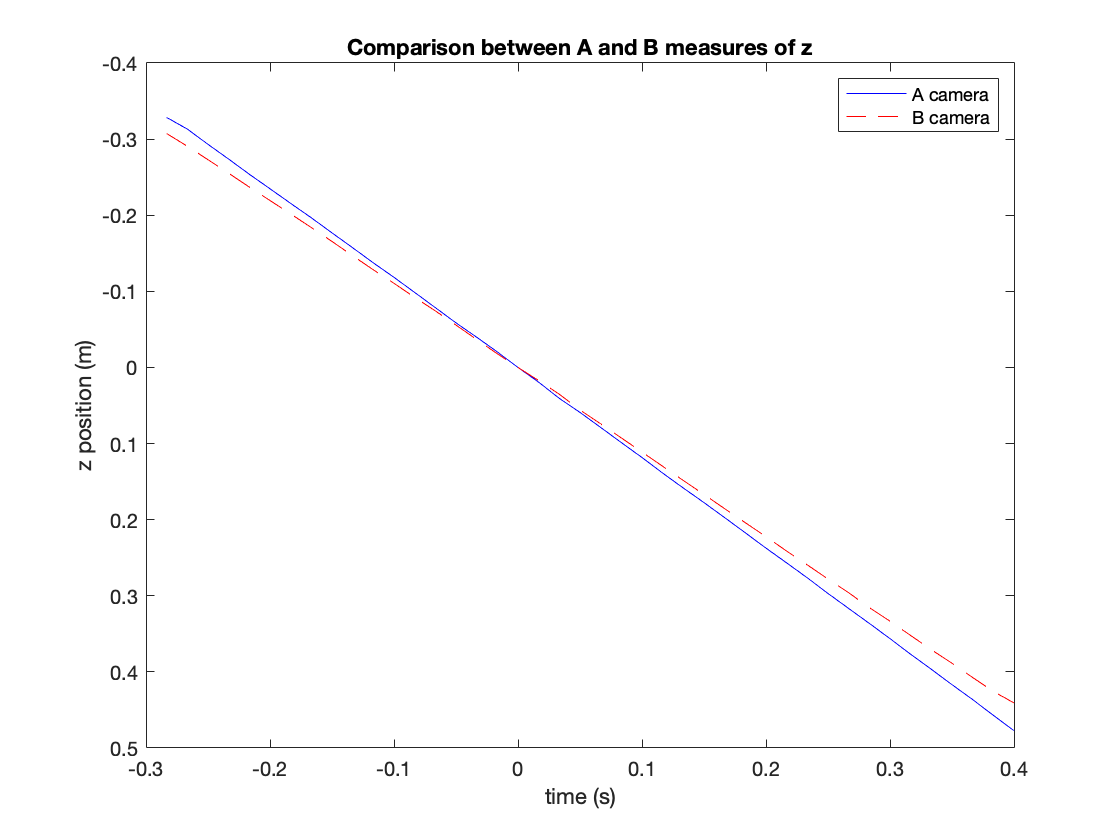

plot(t_A,z_A,"blue",t_B,z_B,"r--")
title("Comparison between A and B measures of z")
ylabel("z position (m)")
xlabel("time (s)")
axis ij
legend(["A camera" "B camera"], "location", "northeast")

To try to quantify the discrepancy between the two, I offer two measurements: first, the maximum difference between any two paired measurements of z divided by the range; second, the average difference between the paired measurements of z divided by the range.

av_range = (range(z_A)+range(z_B))/2;
print1 = ['The maximum difference between any paired measurements as a percentage of the average range is ', num2str(max(abs(z_A-z_B))/av_range*100,3),' percent.'];
disp(print1)

The maximum difference between any paired measurements as a percentage of the average range is 4.69 percent.


print2 = ['The average difference between paired measurements as a percentage of the average range is ', num2str(sum(abs(z_B-z_A))/(av_range*size(z_B,1))*100,3),' percent.'];
disp(print2)

The average difference between paired measurements as a percentage of the average range is 1.81 percent.


Finally, output the three-dimensional track.

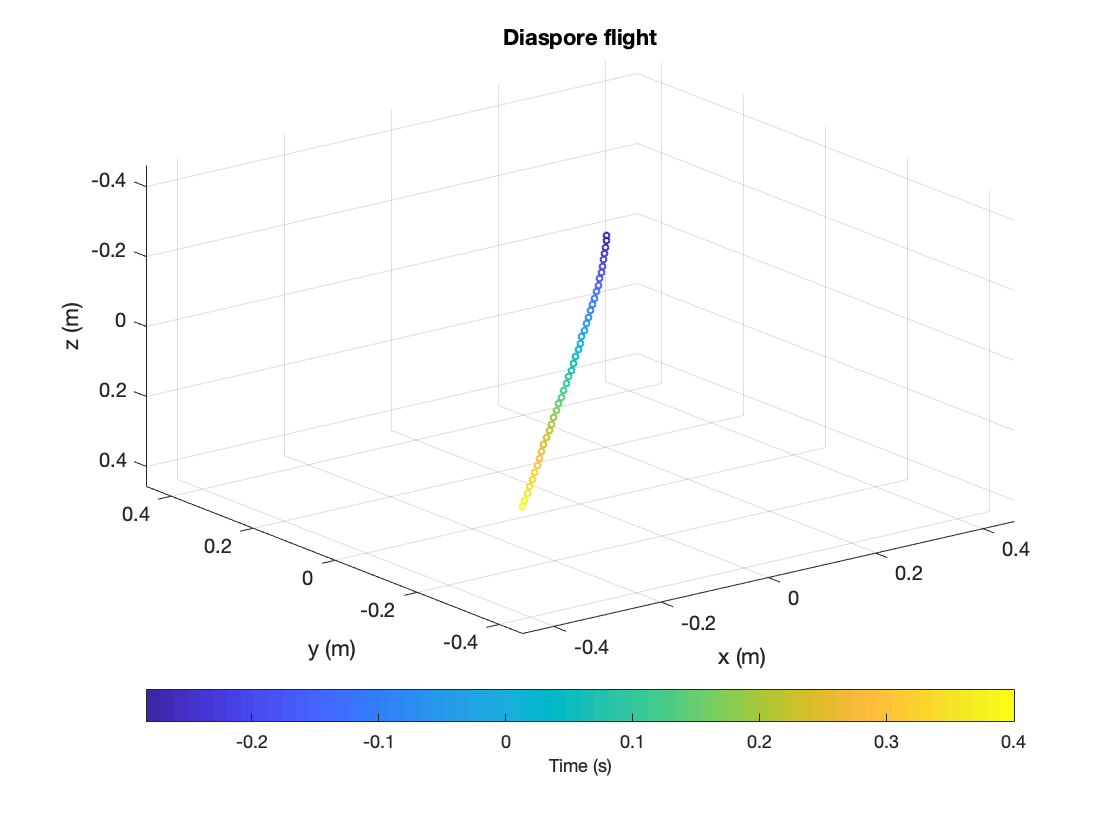

x = x_B*sind(theta);
y = y_A;
z = (z_A+z_B)/2;
t = (t_A+t_B)/2;
axis_max = max(abs(z));
scatter3(x,y,z,10,t)
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
ax = gca;
ax.ZDir = 'reverse';
xlim([-axis_max,axis_max])
ylim([-axis_max,axis_max])
zlim([-axis_max,axis_max])
title("Diaspore flight")
c = colorbar('southoutside');
c.Label.String = 'Time (s)';